Plots kruppel trace at specific ap position (assumes kruppel traces were already loaded)

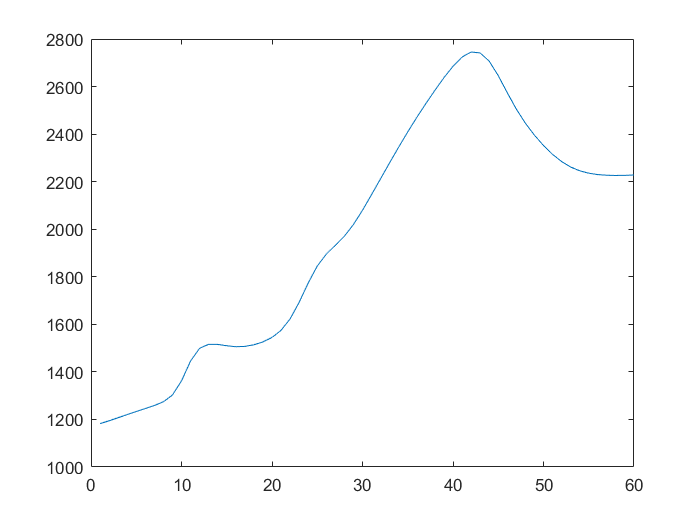


ap = 500;
figure();
plot(KrMov(1:end, ap));

Simulates kruppel eve2 in the case that kruppel just effects the transition rate matrix

% get kruppel traces

krup_traces = cell(1, 131);
for i = 370:500
    trace = KrMov(1:end,i)';
    trace = interp1(0:60:3540, trace, 0:20:3540);
    krup_traces{i - 369} = trace;
end

elong_time = 140;
time_res = 20;
points_per_trace = length(krup_traces{1});
num_traces = 300;
krup_ks = [.000001, .000001];
gen_ks = [.1, .01];
rna_per_sec = [.0001, .2];
fluo_per_rna = 35;
MS2_rise_time = 40;
noise = 0;
[traces, traces_krup] = gen_kruppel_eve2_data(elong_time,time_res, points_per_trace,...
                            num_traces, krup_traces, krup_ks, gen_ks, ...
                            rna_per_sec, fluo_per_rna,MS2_rise_time, ...
                            noise);

Plots individual traces

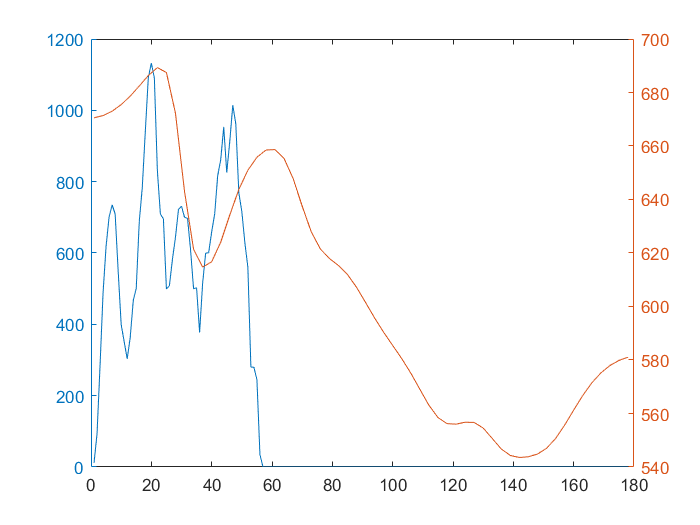

i = 89;
figure();
yyaxis left
plot(traces{i});
yyaxis right
plot(traces_krup{i});

Plots cross correlation

addpath('utilies/');

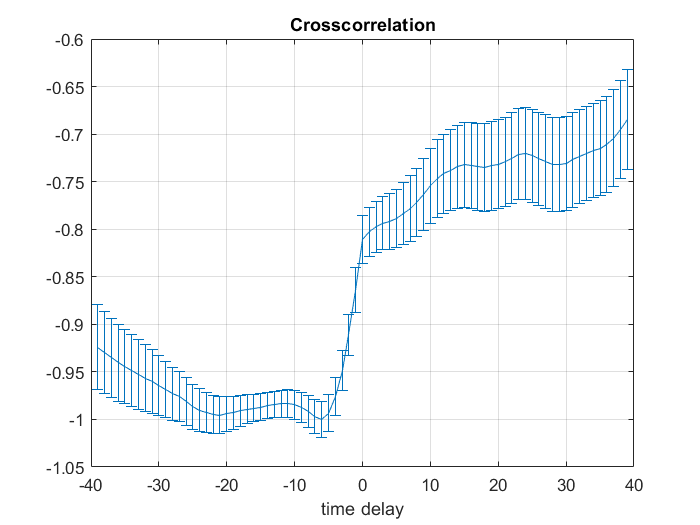


max_delay = 40;
corr = cross_corr_m_calc(traces, traces_krup, max_delay);
deriv1 = corr(2:end) - corr(1:end-1);
deriv2 = deriv1(2:end) - deriv1(1:end-1);
[stds, stds1, stds2] = corr_bootstraps(traces, traces_krup, max_delay, 100, 'm');
figure();
%plot(-max_delay + 1:max_delay - 1, corr)
errorbar(-max_delay + 1:max_delay - 1, corr, stds);
title('Crosscorrelation')
xlabel('time delay')
grid on

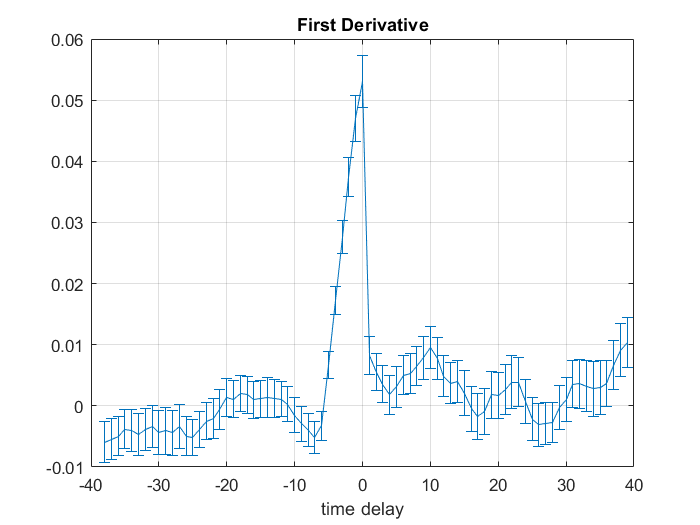


figure();
%plot(-max_delay + 2: max_delay - 1, deriv1);
errorbar(-max_delay + 2: max_delay - 1, deriv1, stds1);
title('First Derivative');
xlabel('time delay')
grid on

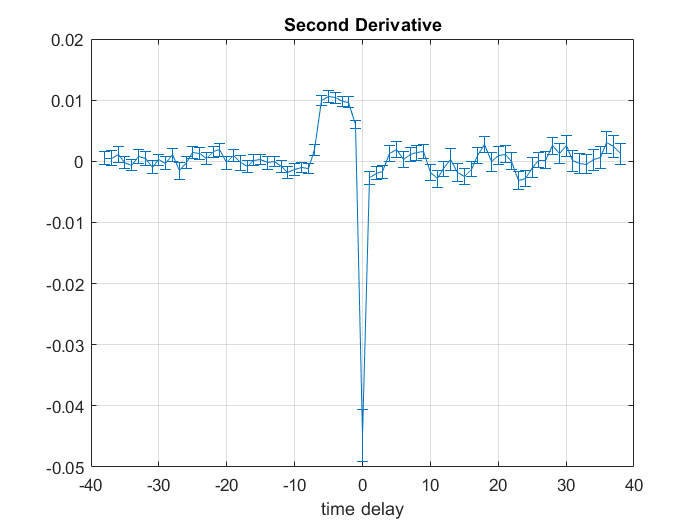


figure();
%plot(-max_delay + 2: max_delay - 2, deriv2);
errorbar(-max_delay + 2: max_delay - 2, deriv2, stds2);
title('Second Derivative');
xlabel('time delay')
grid on